# **AedesNet v2.0**

## **Transferência de aprendizado utilizando a rede alexnet.**

## **Criando o dataset de treinamento, validação e teste.**

imagens = imageDatastore('C:\Users\PF\Documents\treino','IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions',{'.jpg'});

## **Divide o dataset em 60% treino, 20% validação e 20% teste, a escolha das imagens é randomica.**

[trainingImages, valImages ,testImages] = splitEachLabel (imagens, 0.6,0.2,0.2,'randomize');

## Iniciar a rede alexnet na variável cnn.

cnn = alexnet;

## **A variável layers, recebe as camadas rede cnn.**

layers = cnn.Layers 

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

## **Substitui a camadas 23 por outra camada totalmente conectada, com 2 labels (foco e sem foco).** 

layers(23) = fullyConnectedLayer(2);

## **Substitui a camada 25 por outra camada de classificação.**

layers(25) = classificationLayer;

## A primeira camada, image input, requer que a imagem tenha tamanho 227 x 227 x 3, 3 é o número de canais de cor (RGB).

inputSize = cnn.Layers(1).InputSize

inputSize =    227   227     3


# **Aumento de dados**

## imageDataAugmenter realiza reflexões, rotações e corte nas imagens presentes no dataset de treinamento. Dessa forma, consegue multiplicar o número de entradas.

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);

augimdsTrain = augmentedImageDatastore(inputSize,trainingImages, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize,valImages);


# **Paramentros de treinamento da rede.**

**sgdm** = Descida gradiente estocástica com otimizador de impulso (SGDM).

**miniBatchSize** = o mini-batch é um subconjunto do conjunto de treinamento, usado para avaliar o gradiente da função de perda e atualizar os pesos.

**maxEpochs** = número máximo de épocas a ser usadas para treinamento, uma época é um ciclo completo de treinamento em todo o conjunto de dados.

**ValidationFrequency** = validações por época.

**initialLearnRate** = Taxa de aprendizado inicial usada para treinamento..

**verbose** = Indicador para exibir informações de progresso de treinamento na janela de comando, os valores são: 'Verbose' e 1 (true) ou 0 (false).

**plots = 'training-progress'**— traçar o progresso do treinamento. Mostra perda de mini-batch e a precisão, perda de validação e precisão e informações adicionais sobre o andamento do treinamento.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',64, ...
    'MaxEpochs',20, ...
    'InitialLearnRate',0.001, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',50, ...
    'ValidationPatience',Inf, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Treinamento da rede recebendo os parâmetros: imagens de treino, camadas de rede e opções de treino

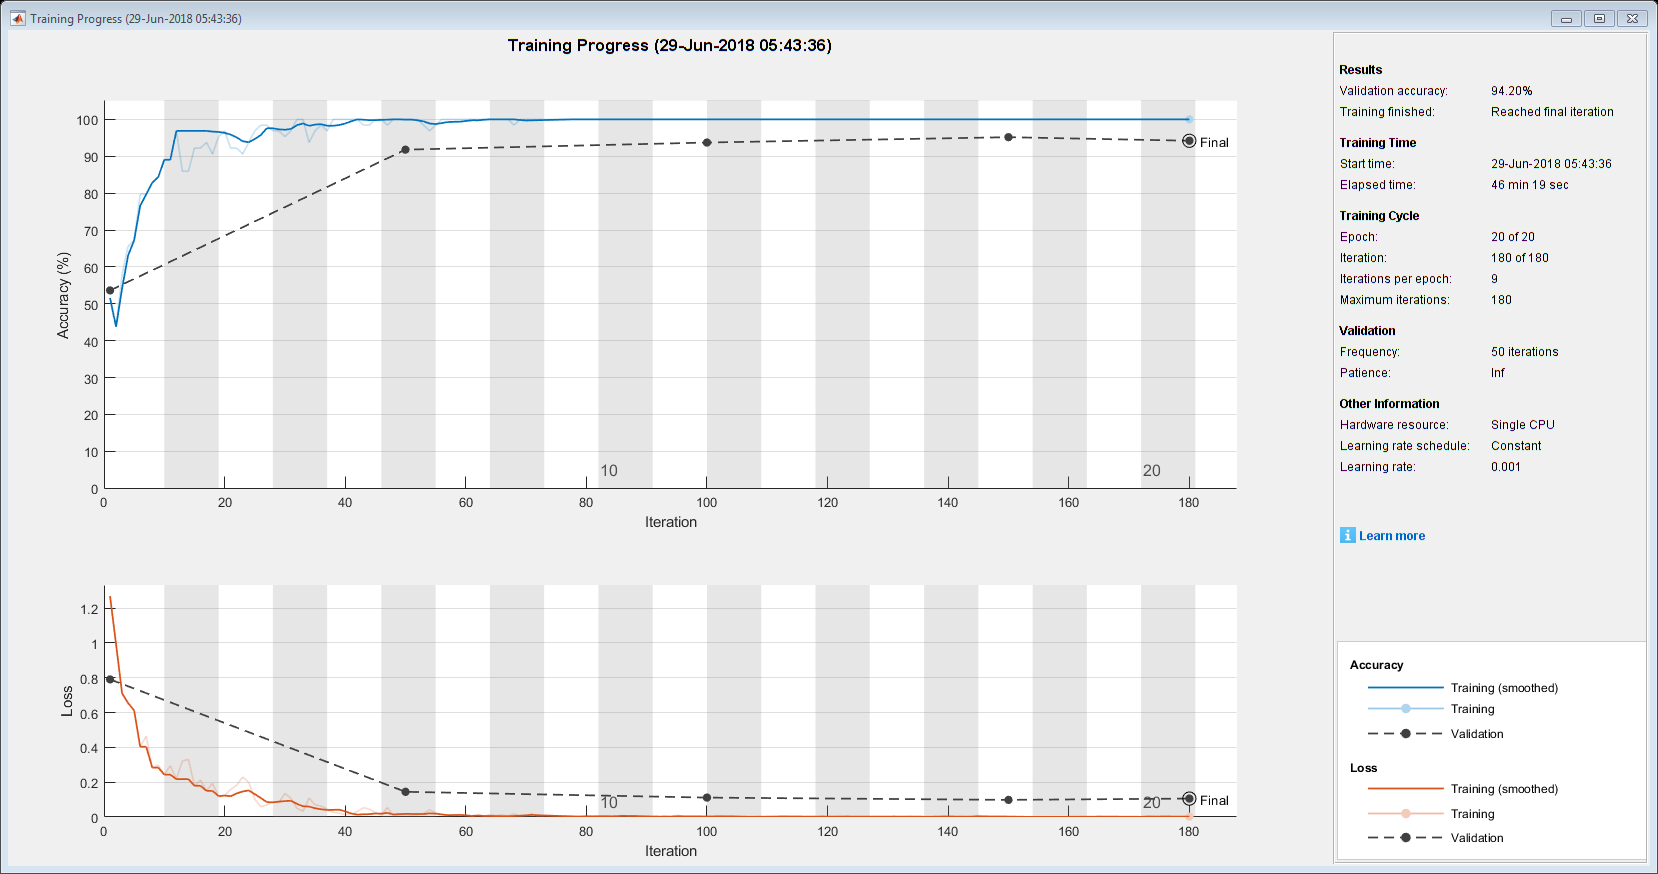

rede = trainNetwork(trainingImages, layers, options);

## Classificação

predictedLabels = classify(rede, testImages); 


## Precisão da Rede


accuracy = mean(predictedLabels == testImages.Labels)

accuracy = 0.9663

Pedro filho